# COTS Ensemble Live Script 22

## Set Interpreter

setInterpLatex()

## Contents

More Figures for Morgan

Connectivitiy CoP Figures

Redoing Competency and Survivorship Figures

KS Test for Larval Settlement

Additional Paper Figures

Graph-theoretic Metrics

Distance-based Connectivity Comparison

## Assumptions

## Self-recruitment Levels

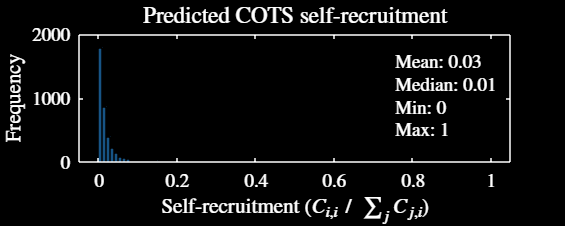

% in case reviewers get pissed off, let's look at self-recruitment levels
% real quick
selfRec = zeros(nReefs, 1);
for i = 1:nReefs
    selfRec(i) = replaceNaNs(conMatGlobal(i, i), 0) ...
        / sum(replaceNaNs(conMatGlobal(:, i), 0));
end
figure
figResize(0.8, 1.5)
histogram(selfRec, 100, 'EdgeColor', 'k')
ylabel("Frequency")
xlabel("Self-recruitment ($C_{i, i} \,\, / \,\, \sum_j C_{j, i}$)")
title("Predicted COTS self-recruitment")
text(0.75, 1750, ["Mean: " + round(mean(removeNaNs(selfRec)), 2), ...
    "Median: " + round(median(removeNaNs(selfRec)), 2), "Min: " ...
    + round(min(selfRec), 2), "Max: " + round(max(selfRec), 2)], ...
    'HorizontalAlignment', 'left', 'VerticalAlignment', 'top')
setFontSize(16)
darkFig()
saveFig("selfRecHistDM")
lightFig()
saveFig("selfRecHist")
darkFig()

## Redoing Competency and Survivorship Figures

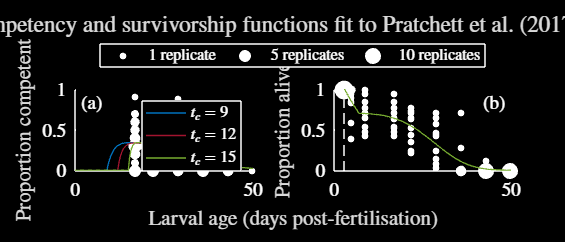

% seems I will need to loop over this for the
tVec = linspace(0, 50, 201);
figure

% plot the competency
figResize(1, 1.75)
tL = tiledlayout(1, 2, 'tilespacing', 'compact');
nexttile()
hold on

% plot the lines first just so the legend isn't a headache
load("../Data/competencySurvivorshipData/compSurvAll.mat")
probVec = compFuncWeibExp(tVec, paramsStructComp);
plot(tVec, probVec, '-', "Color", getColour('b'), ...
    'LineWidth', 1)
load("../Data/competencySurvivorshipData/compSurvTc12.mat")
probVec = compFuncWeibExp(tVec, paramsStructComp);
plot(tVec, probVec, '-', "Color", getColour('r'), ...
    'LineWidth', 1)
load("../Data/competencySurvivorshipData/compSurvTc15.mat")
probVec = compFuncWeibExp(tVec, paramsStructComp);
plot(tVec, probVec, '-', "Color", getColour('g'), ...
    'LineWidth', 1)

% just plot the points by size
[var1, var2] = uniqueAndCount(compDataPerc, "rows");
var3 = unique(var2);
var5 = @(x) 2 * (1.5 * x + 6);
for j = 1:length(var3)
    var4 = var2 == var3(j);
    plot(var1(var4, 1), var1(var4, 2), 'k.', 'MarkerSize', ...
        var5(var3(j)));
end

% now plot the rest
load("../Data/competencySurvivorshipData/compSurvAll.mat")
probVec = compFuncWeibExp(tVec, paramsStructComp);
plot(tVec, probVec, '-', "Color", getColour('b'), ...
    'LineWidth', 1)
load("../Data/competencySurvivorshipData/compSurvTc12.mat")
probVec = compFuncWeibExp(tVec, paramsStructComp);
plot(tVec, probVec, '-', "Color", getColour('r'), ...
    'LineWidth', 1)
load("../Data/competencySurvivorshipData/compSurvTc15.mat")
probVec = compFuncWeibExp(tVec, paramsStructComp);
plot(tVec, probVec, '-', "Color", getColour('g'), ...
    'LineWidth', 1)
legend("$t_c = 9$", "$t_c = 12$", "$t_c = 15$")
ylim([-0.01, 1])
ylabel('Proportion competent')
subfigLabel("(a)", 'northwest')

% now plot the survivorship
nexttile()
hold on
tVec = linspace(3, 50, 201);

% plot some dummy points
[var1, var2] = uniqueAndCount(survDataDec, "rows");
var3 = [1, 5, 10];
for j = 1:length(var3)
    plot(1, 100, 'k.', 'MarkerSize', var5(var3(j)));
end

% now plot the actual points
var3 = unique(var2);
for j = 1:length(var3)
    var4 = var2 == var3(j);
    plot(var1(var4, 1), var1(var4, 2), 'k.', 'MarkerSize', ...
        var5(var3(j)));
end
xline(3, '--k')
load("../Data/competencySurvivorshipData/compSurvAll.mat")
probVec = survFuncWeibWeib(tVec, paramsStructSurv);
probVec = probVec / probVec(1);
plot(tVec, probVec, '-', "Color", getColour('g'), ...
    'LineWidth', 1)
lG = legend("1 replicate", "5 replicates", "10 replicates", ...
    'location', 'northoutside', 'orientation', 'horizontal');
lG.Layout.Tile = 'North';
ylim([-0.01, 1])
box off
ylabel('Proportion alive')
subfigLabel("(b)", 'northeast')

% pretty up the figure
title(tL, ['Competency and survivorship functions fit to ' ...
    'Pratchett et al. (2017) data'], ...
    'interpreter', 'latex')
xlabel(tL, 'Larval age (days post-fertilisation)', ...
    'interpreter', 'latex')
setFontSize(16)
lightFig()
saveFig("compSurvCurvesFit")
darkFig()
saveFig("compSurvCurvesFitDM")

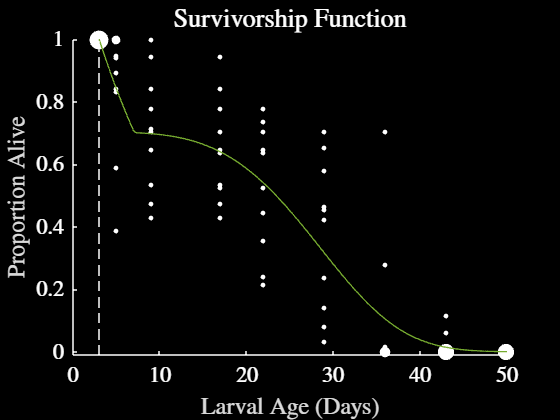

% recreate the curves below
figure
hold on
tVec = linspace(3, 50, 201);
[var1, var2] = uniqueAndCount(survDataDec, "rows");
scatter(var1(:, 1), var1(:, 2), 4 * (0.1 * var2.^2 + 3 * var2), ...
    'k', 'filled')
xline(3, '--k')
load("../Data/competencySurvivorshipData/compSurvAll.mat")
probVec = survFuncWeibWeib(tVec, paramsStructSurv);
probVec = probVec / probVec(1);
plot(tVec, probVec, '-', "Color", getColour('g'), ...
    'LineWidth', 1)
ylim([-0.01, 1])
xlabel('Larval Age (Days)')
ylabel('Proportion Alive')
title('Survivorship Function')
setFontSize(18)
lightFig()
saveFig("survCurve")
scatter(var1(:, 1), var1(:, 2), 4 * (0.2 * var2.^2 + 3 * var2), ...
    'w', 'filled')
tVec = linspace(3, 50, 201);
probVec = survFuncWeibWeib(tVec, paramsStructSurv);
probVec = probVec / probVec(1);
plot(tVec, probVec, '-', "Color", getColour('g'), ...
    'LineWidth', 1)
darkFig()
saveFig("survCurvDM")

## KS Test for Larval Settlement

% alright let's do the final one, where I'm using the brt for both mean and
% median, and then the knn for the maximum
cotsDensData = readtable("../Data/Matlab Transfer/cotsDensBrtV3.csv");
var1 = readtable("../Data/Matlab Transfer/cotsDensKnn.csv");
cotsDensData.cotsPerTowMaxImput = var1.cotsPerTowMaxImput;

% alright, now need to load in the outbreaking data
outbreakDataMatlab = readtable("../Data/Matlab Transfer/" + ...
    "outbreakDataMatlab");
outbreakData = readtable("../Data/Matlab Transfer/outbreakData");

% let's make some masks so that my life is easier
outbrReefs = outbreakDataMatlab.outbreak == 1;
nonOutbrReefs = outbreakDataMatlab.outbreak == 0;
obsReefs = (outbreakDataMatlab.outbreak == 0) ...
    + (outbreakDataMatlab.outbreak == 1) > 0;

% calculate the number of incoming larvae for each of the estimations
var5 = ["Mean", "Median", "Max"];
for j = 1:3

    % calculate the number of incoming larvae
    conStrengthsInSum = replaceNaNs(conMatGlobal', 0) * ...
        ((replaceNaNs(cotsDensData{:, "cotsPerTow" + var5(j) + "Imput"}, ...
        0) .* replaceNaNs(cotsDensData.area, 0)));
    var1 = [conStrengthsInSum(nonOutbrReefs); ...
        conStrengthsInSum(outbrReefs)];
    var2 = [zeros(size(conStrengthsInSum(nonOutbrReefs))); ...
        ones(size(conStrengthsInSum(outbrReefs)))];

    % throw out some summary statistics
    fprintf(var5(j) + "\n")
    fprintf("Mean non-outbreaks: ")
    mean(conStrengthsInSum(nonOutbrReefs))
    fprintf("Mean outbreaks: ")
    mean(conStrengthsInSum(outbrReefs))

    % run the ks test
    fprintf("KS test")
    [~, p] = kstest2(conStrengthsInSum(nonOutbrReefs), ...
        conStrengthsInSum(outbrReefs))

    % run the median test
    fprintf("Median test")
    p = mediantest(conStrengthsInSum(nonOutbrReefs), ...
        conStrengthsInSum(outbrReefs))

end

Mean


Mean non-outbreaks: 

ans = 4.3363e+05

Mean outbreaks: 

ans = 7.9930e+05

KS test

p = 1.9545e-05

Median test

p = 4.8913e-06

Median


Mean non-outbreaks: 

ans = 6.0558e+04

Mean outbreaks: 

ans = 8.9112e+04

KS test

p = 0.0011

Median test

p = 7.8158e-04

Max


Mean non-outbreaks: 

ans = 2.5194e+06

Mean outbreaks: 

ans = 5.3534e+06

KS test

p = 2.0788e-09

Median test

p = 7.4900e-09

## Additional Paper Figures

% alright, now need to load in the outbreaking data
outbreakDataMatlab = readtable("../Data/Matlab Transfer/" + ...
    "outbreakDataMatlab");
outbreakData = readtable("../Data/Matlab Transfer/outbreakData");

% let's make some masks so that my life is easier
outbrReefs = outbreakDataMatlab.outbreak == 1;
nonOutbrReefs = outbreakDataMatlab.outbreak == 0;
obsReefs = (outbreakDataMatlab.outbreak == 0) ...
    + (outbreakDataMatlab.outbreak == 1) > 0;

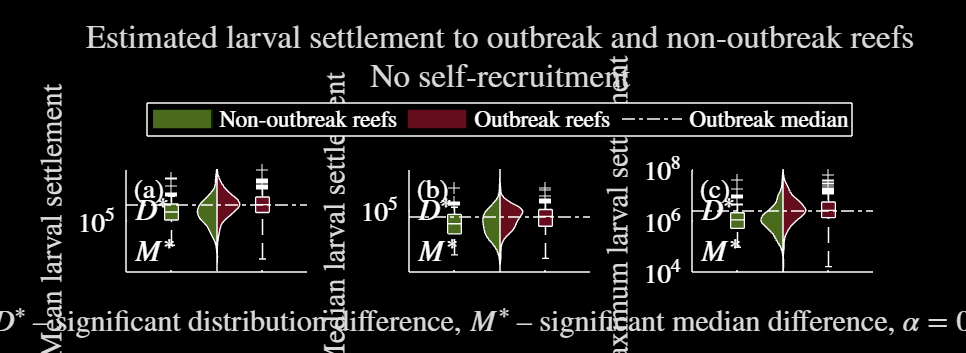

cotsPerTowMeanImput
Mean non-outbreaks: 

ans = 4.2843e+05

Mean outbreaks: 

ans = 7.1642e+05

KS test

p = 6.1794e-05

Median test

p = 1.5090e-05

--------------------------------------------------
cotsPerTowMedianImput
Mean non-outbreaks: 

ans = 5.9562e+04

Mean outbreaks: 

ans = 8.5031e+04

KS test

p = 0.0033

Median test

p = 7.8158e-04

--------------------------------------------------
cotsPerTowMaxImput
Mean non-outbreaks: 

ans = 2.4891e+06

Mean outbreaks: 

ans = 4.8210e+06

KS test

p = 4.4286e-09

Median test

p = 7.4900e-09

--------------------------------------------------


% alright let's do the final one, where I'm using the brt for both mean and
% median, and then the knn for the maximum
cotsDensBrt = readtable("../Data/Matlab Transfer/cotsDensBrtV3.csv");
var1 = readtable("../Data/Matlab Transfer/cotsDensKnn.csv");
cotsDensBrt.cotsPerTowMaxImput = var1.cotsPerTowMaxImput;

% let's redo the boxplots without self recruitment
var1 = ["", "DM"];
figure
figResize(1.5, 2)
for i = 1:2
    clf()
    plotLarvalSupplyV2(cotsDensBrt, conMatGlobal - diag(diag(conMatGlobal)), ...
        nonOutbrReefs, outbrReefs, ["Estimated larval settlement " + ...
        "to outbreak and non-outbreak reefs", "No self-recruitment"], ...
        i == 2, false)
    saveFig("estimatedLarvSuppNoSR" + var1(i))
end

% alright let's do the final one, where I'm using the brt for both mean and
% median, and then the knn for the maximum
cotsDensData = readtable("../Data/Matlab Transfer/cotsDensBrtV3.csv");
var1 = readtable("../Data/Matlab Transfer/cotsDensKnn.csv");
cotsDensData.cotsPerTowMaxImput = var1.cotsPerTowMaxImput;

% alright, now need to load in the outbreaking data
outbreakDataMatlab = readtable("../Data/Matlab Transfer/" + ...
    "outbreakDataMatlab");
outbreakData = readtable("../Data/Matlab Transfer/outbreakData");

% let's make some masks so that my life is easier
outbrReefs = outbreakDataMatlab.outbreak == 1;
nonOutbrReefs = outbreakDataMatlab.outbreak == 0;
obsReefs = (outbreakDataMatlab.outbreak == 0) ...
    + (outbreakDataMatlab.outbreak == 1) > 0;

% let's also redo the ks test and median test stuff
% calculate the number of incoming larvae for each of the estimations
var5 = ["Mean", "Median", "Max"];
for j = 1:3

    % calculate the number of incoming larvae
    conStrengthsInSum = replaceNaNs((conMatGlobal ...
        - diag(diag(conMatGlobal)))', 0) * ...
        ((replaceNaNs(cotsDensData{:, "cotsPerTow" + var5(j) ...
        + "Imput"}, 0) .* replaceNaNs(cotsDensData.area, 0)));
    var1 = [conStrengthsInSum(nonOutbrReefs); ...
        conStrengthsInSum(outbrReefs)];
    var2 = [zeros(size(conStrengthsInSum(nonOutbrReefs))); ...
        ones(size(conStrengthsInSum(outbrReefs)))];

    % throw out some summary statistics
    fprintf(var5(j) + "\n")
    fprintf("Mean non-outbreaks: ")
    mean(conStrengthsInSum(nonOutbrReefs))
    fprintf("Mean outbreaks: ")
    mean(conStrengthsInSum(outbrReefs))

    % run the ks test
    fprintf("KS test")
    [~, p] = kstest2(conStrengthsInSum(nonOutbrReefs), ...
        conStrengthsInSum(outbrReefs))

    % run the median test
    fprintf("Median test")
    p = mediantest(conStrengthsInSum(nonOutbrReefs), ...
        conStrengthsInSum(outbrReefs))

end

Mean


Mean non-outbreaks: 

ans = 4.2843e+05

Mean outbreaks: 

ans = 7.1642e+05

KS test

p = 6.1794e-05

Median test

p = 1.5090e-05

Median


Mean non-outbreaks: 

ans = 5.9562e+04

Mean outbreaks: 

ans = 8.5031e+04

KS test

p = 0.0033

Median test

p = 7.8158e-04

Max


Mean non-outbreaks: 

ans = 2.4891e+06

Mean outbreaks: 

ans = 4.8210e+06

KS test

p = 4.4286e-09

Median test

p = 7.4900e-09

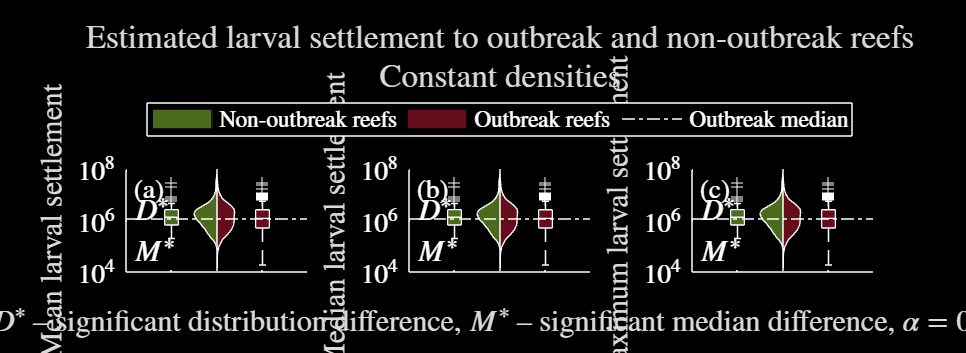

cotsPerTowMeanImput
Mean non-outbreaks: 

ans = 2.4472e+06

Mean outbreaks: 

ans = 2.2008e+06

KS test

p = 0.2535

Median test

p = 0.3186

--------------------------------------------------
cotsPerTowMedianImput
Mean non-outbreaks: 

ans = 2.4472e+06

Mean outbreaks: 

ans = 2.2008e+06

KS test

p = 0.2535

Median test

p = 0.3186

--------------------------------------------------
cotsPerTowMaxImput
Mean non-outbreaks: 

ans = 2.4472e+06

Mean outbreaks: 

ans = 2.2008e+06

KS test

p = 0.2535

Median test

p = 0.3186

--------------------------------------------------


Const. dens. settlement
Mean non-outbreaks: 

ans = 2.4472e+06

Mean outbreaks: 

ans = 2.2008e+06

KS test

p = 0.2535

Median test

p = 0.3186

--------------------------------------------------
In-degree
Mean non-outbreaks: 

ans = 1.2052e+03

Mean outbreaks: 

ans = 1.1791e+03

KS test

p = 0.5290

Median test

p = 0.4859

--------------------------------------------------
Subs. in-degree
Mean non-outbreaks: 

ans = 33.9556

Mean outbreaks: 

ans = 34.8551

KS test

p = 0.0791

Median test

p = 0.6552

--------------------------------------------------
Subs. in-component
Mean non-outbreaks: 

ans = 653.4222

Mean outbreaks: 

ans = 508.3498

KS test

p = 0.0234

Median test

p = 0.1236

--------------------------------------------------
Local retention
Mean non-outbreaks: 

ans = 0.0048

Mean outbreaks: 

ans = 0.0042

KS test

p = 0.0026

Median test

p = 6.3167e-04

--------------------------------------------------
Subs. clustering
Mean non-outbreaks: 

ans = 6.4248

Mean outbreaks: 

ans = 5.7875

KS test

p = 0.1042

Median test

p = 0.0848

--------------------------------------------------
PageRank
Mean non-outbreaks: 

ans = 3.0230e-04

Mean outbreaks: 

ans = 3.3285e-04

KS test

p = 0.1584

Median test

p = 0.0316

--------------------------------------------------
Authority score
Mean non-outbreaks: 

ans = 3.1540e-04

Mean outbreaks: 

ans = 1.4208e-04

KS test

p = 2.6147e-04

Median test

p = 6.3167e-04

--------------------------------------------------


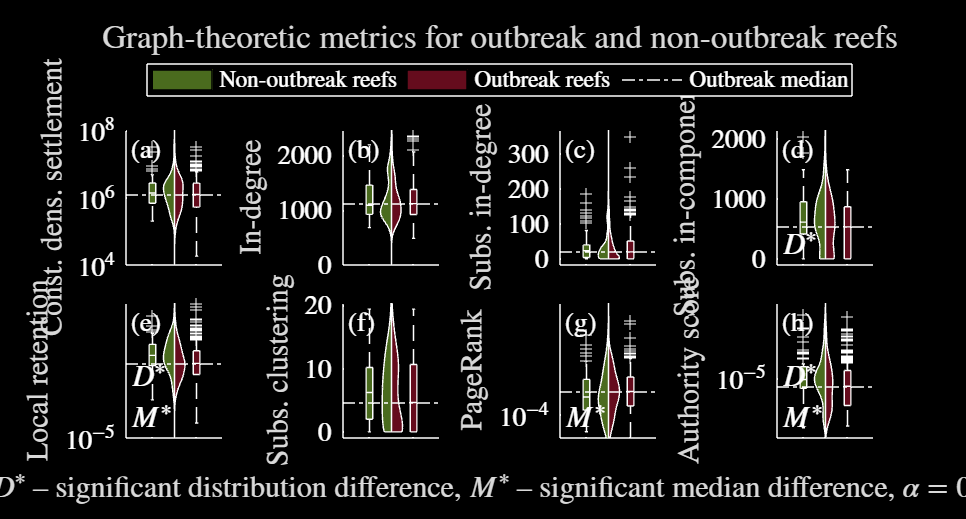

% alright let's do one with constant density settlement
cotsDensBrt = readtable("../Data/Matlab Transfer/cotsDensBrtV3.csv");
cotsDensBrt.cotsPerTowMaxImput = ones(size(cotsDensBrt.cotsPerTowMaxImput));
cotsDensBrt.cotsPerTowMeanImput = ones(size(cotsDensBrt.cotsPerTowMaxImput));
cotsDensBrt.cotsPerTowMedianImput = ones(size(cotsDensBrt.cotsPerTowMaxImput));

% let's redo the boxplots without self recruitment
var1 = ["", "DM"];
figure
figResize(1.5, 2)
for i = 1:2
    clf()
    plotLarvalSupplyV2(cotsDensBrt, conMatGlobal, ...
        nonOutbrReefs, outbrReefs, ["Estimated larval settlement to " + ...
        "outbreak and non-outbreak reefs", "Constant densities"], ...
        i == 2, false)
    saveFig("estimatedLarvSuppConstDens" + var1(i))
end